# **Signals & Systems - CA2 - Dr Akhavan**

## Amirali Dehghani - 810102443

### Part 1

clc, clearvars, close all;

#### 1 - 1) Reading Data

[file, path] = uigetfile({'*.jpg;*.png'}, "Choose plate's image: ");
platePicture = imread([path, file]);

#### 1 - 2)  Resizing picture

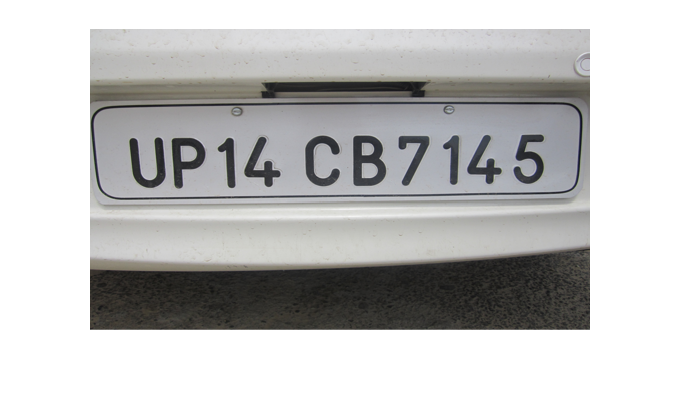

resizedPicture = imresize(platePicture, [300 500]);
figure;
imshow(resizedPicture);

#### 1 - 3) Grayscalinggrayscaled picture

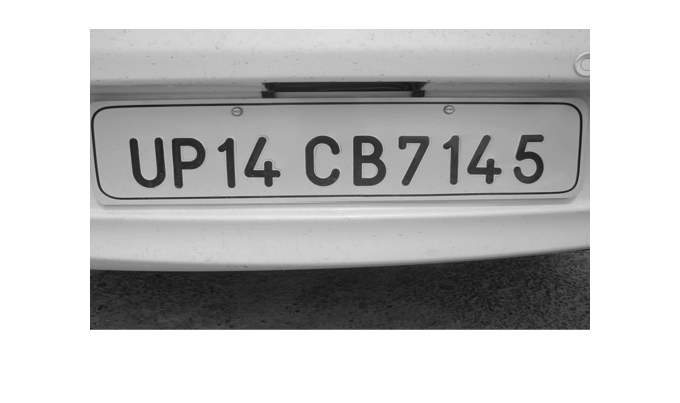

grayscaledPicture = mygrayfun(resizedPicture);
figure;
imshow(grayscaledPicture);

#### 1 - 4) Binarizing picture

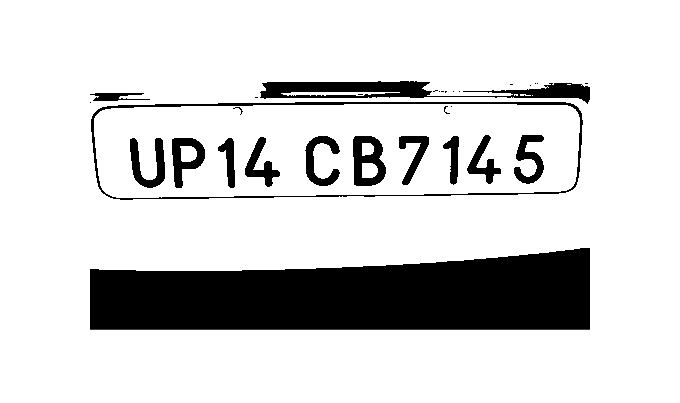

threshold = 100;
binarizedPicture = mybinaryfun(grayscaledPicture, threshold);
figure;
imshow(binarizedPicture);

#### 1 - 5) Removing noises

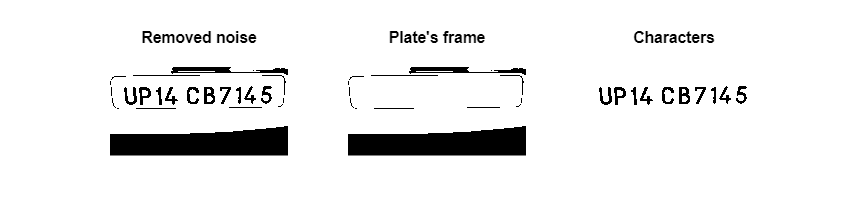


filtered = myremovecom(~binarizedPicture, 300);
background = myremovecom(~binarizedPicture, 2300);
characters = (filtered - background);

figure('Position', [0 0 800 200]);

subplot(1,3,1);
imshow(~filtered);
title('Removed noise');

subplot(1,3,2);
imshow(~background);
title('Plate''s frame');

subplot(1,3,3);
imshow(~characters);
title('Characters');

#### 1 - 6) Detecting segments

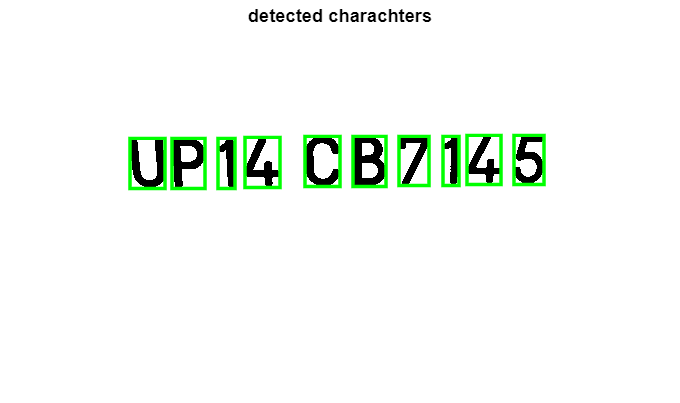

[labeled, n] = mysegmentation(characters);
figure('Position', [0 0 100 100]);
propied=regionprops(labeled,'BoundingBox');
imshow(~characters);
title('detected charachters')
hold on
for m=1:size(propied,1)
    rectangle('Position',propied(m).BoundingBox,'EdgeColor','g','LineWidth',2)
end
hold off

#### 1 - 7) Importing database & Detecting plate

englishMapSet = getMapSet('./EnglishMapSet');
detectedPlate = '';
for i = 1:n
    [row, col] = find(labeled == i);
    y = characters(min(row):max(row), min(col):max(col));
    y = imresize(y,[42,24]);
    corr_max = -2;
    i_max = 0;
    for j = 1:length(englishMapSet)
        y = imresize(y,size(englishMapSet{j,1}));
        corr_j = corr2(y,englishMapSet{j,1});
        if(corr_j > corr_max)
            corr_max = corr_j;
            i_max = j;
        end
    end
    if(corr_max > 0.3)
        detectedPlate = strcat(detectedPlate,englishMapSet{i_max,2});
    end
end

#### 1 - 8) Printing detected plate and writing it in a file

outputFile = fopen("output.txt", "a");
fprintf(outputFile, "Picture : %s Plate number : %s \n", file, detectedPlate);
fclose(outputFile);
fprintf("Picture : %s Plate number : %s \n", file, detectedPlate);

Picture : image3.JPG Plate number : UP14CB7145 


### Part 2

clc, clearvars, close all;

#### 2 - 1) Reading Data

[file, path] = uigetfile({'*.jpg;*.png'}, "Choose plate's image: ");
platePicture = imread([path, file]);

#### 2 - 2)  Resizing picture

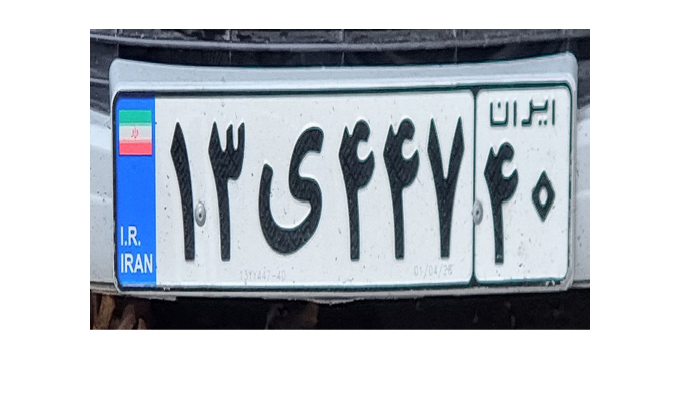

resizedPicture = imresize(platePicture, [300 500]);
figure;
imshow(resizedPicture);

#### 2 - 3) Grayscalinggrayscaled picture

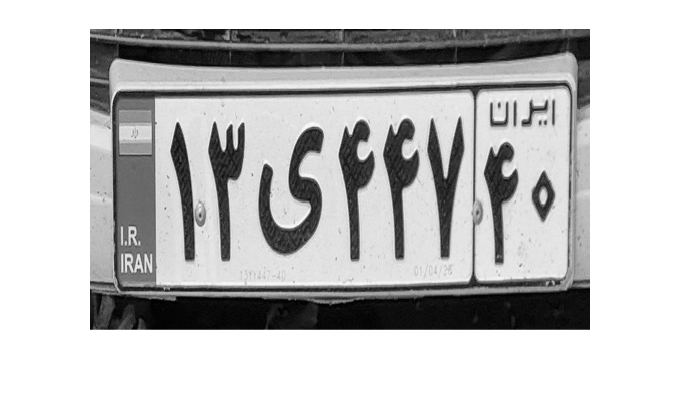

grayscaledPicture = mygrayfun(resizedPicture);
figure;
imshow(grayscaledPicture);

#### 2 - 4) Binarizing picture

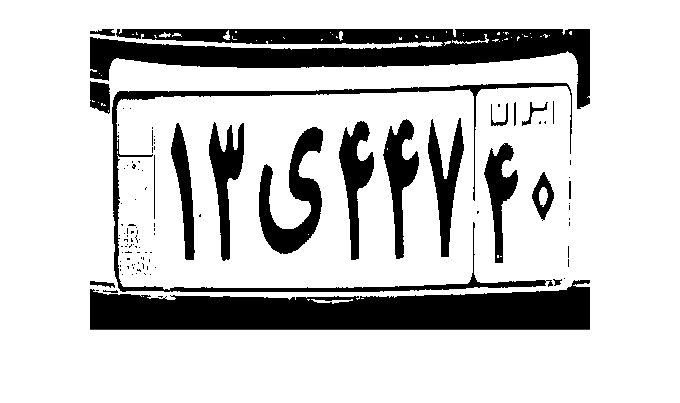

threshold = 100;
binarizedPicture = mybinaryfun(grayscaledPicture, threshold);
figure;
imshow(binarizedPicture);

#### 2 - 5) Removing noises

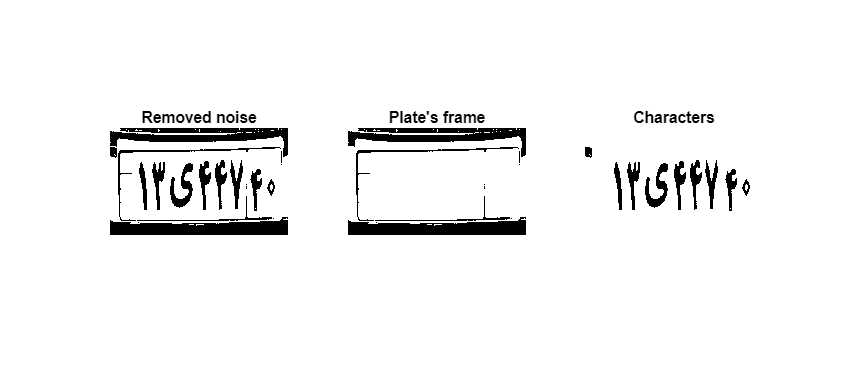


filtered = myremovecom(~binarizedPicture, 400);
background = myremovecom(~binarizedPicture, 5000);
characters = (filtered - background);

figure('Position', [0 0 900 400]);

subplot(1,3,1);
imshow(~filtered);
title('Removed noise');

subplot(1,3,2);
imshow(~background);
title('Plate''s frame');

subplot(1,3,3);
imshow(~characters);
title('Characters');

#### 2 - 6) Detecting segments

[labeled, n] = mysegmentation(characters);
fprintf("Number of segments: %d", n);

Number of segments: 9

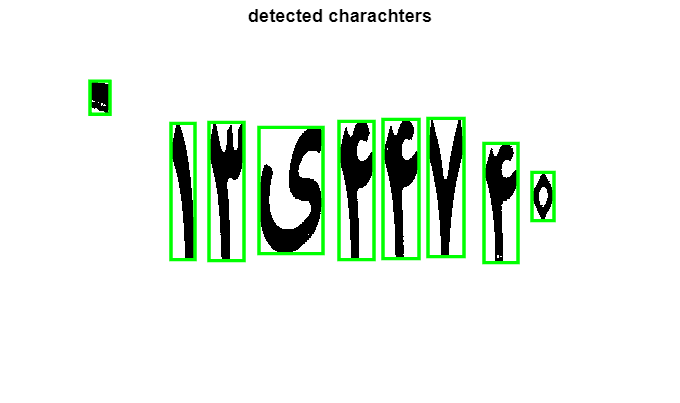

figure('Position', [0 0 800 300]);
propied=regionprops(labeled,'BoundingBox');
imshow(~characters);
title('detected charachters')
hold on
for m=1:size(propied,1)
    rectangle('Position',propied(m).BoundingBox,'EdgeColor','g','LineWidth',2)
end
hold off

#### 2 - 7) Importing database & Detecting plate

persianMapSet = getMapSet('./PersianMapSet');
detectedPlate = '';
for i = 1:n
    [row, col] = find(labeled == i);
    y = characters(min(row):max(row), min(col):max(col));
    corr_max = -2;
    i_max = 0;
    for j = 1:length(persianMapSet)
        character = persianMapSet{j, 2};
        y = imresize(y, size(persianMapSet{j,1}));
        corr_j = corr2(y, persianMapSet{j,1});
        if corr_j > corr_max
            corr_max = corr_j;
            i_max = j;
        end
    end
    if corr_max > 0.3
        detectedPlate = strcat(detectedPlate, persianMapSet{i_max,2});
    end
end

#### 2 - 8) Printing detected plate and writing it in a file

outputFile = fopen("output.txt", "a");
fprintf(outputFile, "Picture : %s Plate number : %s \n", file, detectedPlate);
fclose(outputFile);
fprintf("Picture : %s Plate number : %s \n", file, detectedPlate);

Picture : 2.jpg Plate number : 13Y44740 


### Part 3

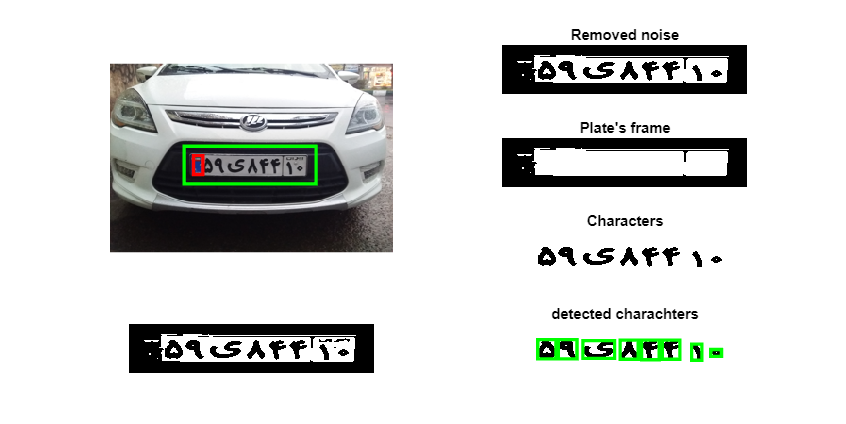

Picture : p3/1.jpg Plate number : 59Y84410 


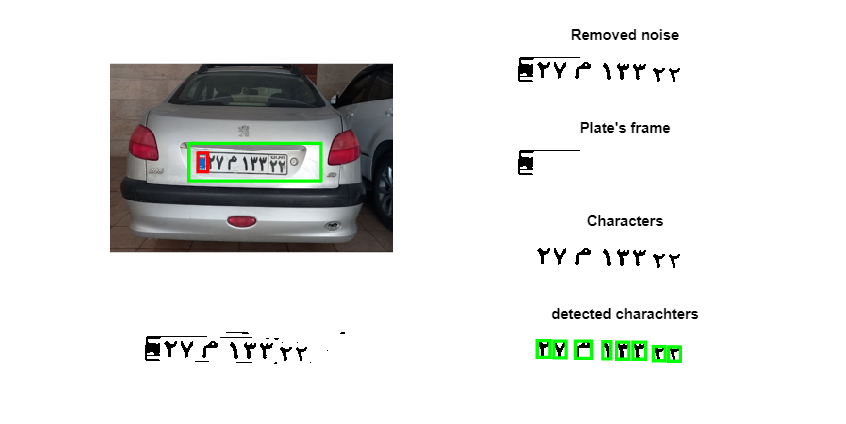

Picture : p3/2.jpg Plate number : 27M13322 


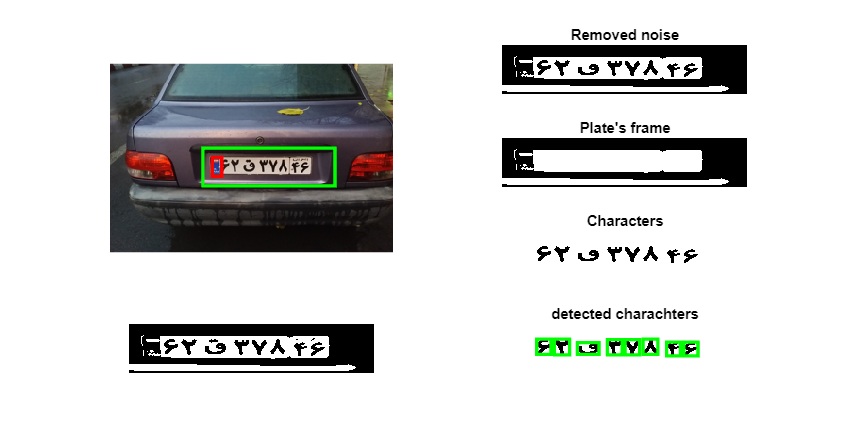

Picture : p3/3.jpg Plate number : 62GH37846 


clc, clearvars, close all;
template = imread('origin.jpg');
filedest = "p3/";
persianMapSet = getMapSet('./PersianMapSet');
for k = 1:3
    file = filedest + k + ".jpg";
    image = imread(file);
    image = imresize(image, [200, 300]);
    template = imresize(template, [20, 10]); 
    
    template = im2double(template);
    image = im2double(image);
    
    correlationMapR = normxcorr2(template(:,:,1), image(:,:,1));
    correlationMapG = normxcorr2(template(:,:,2), image(:,:,2));
    correlationMapB = normxcorr2(template(:,:,3), image(:,:,3));
    wR = 1;
    wG = 1;
    wB = 1;
    correlationMap = (wR * correlationMapR + wG * correlationMapG + wB * correlationMapB) / (wR + wG + wB);
    
    [maxCorrelationValue, maxIndex] = max(correlationMap(:));
    [maxRow, maxCol] = ind2sub(size(correlationMap), maxIndex);
    templateHeight = size(template, 1);
    templateWidth = size(template, 2);
    matchedRegionRow = maxRow - templateHeight + 1;
    matchedRegionCol = maxCol - templateWidth + 1;
    
    
    figure('Position',[0, 0, 800 400]);
    subplot(4,2,[1 3 5]);
    imshow(image);
    hold on;
    rectangle('Position', [matchedRegionCol, matchedRegionRow, templateWidth, templateHeight], 'EdgeColor', 'r', 'LineWidth', 2);
    rectangle('Position', [matchedRegionCol-10, matchedRegionRow-10, 7 * templateHeight, 2 * templateHeight], 'EdgeColor', 'g', 'LineWidth', 2);
    hold off;
    plate = imcrop(image, [matchedRegionCol-10, matchedRegionRow-10, 7 * templateHeight, 2 * templateHeight]);
    subplot(4,2,7);mybinaryfun(mygrayfun(imresize(plate, [100, 500])), 0.4);
    plate = mybinaryfun(mygrayfun(imresize(plate, [100, 500])), 0.4);
    imshow(plate);
    
    filtered = myremovecom(~plate, 170);
    background = myremovecom(~plate, 1200);
    characters = (filtered - background);
        
    subplot(4,2,2);
    imshow(~filtered);
    title('Removed noise');
    
    subplot(4,2,4);
    imshow(~background);
    title('Plate''s frame');
    
    subplot(4,2,6);
    imshow(~characters);
    title('Characters'); 
   
    detectedPlate = '';
    subplot(4,2,8)
    imshow(~characters);
    
    [labeled, n] = mysegmentation(characters);
    propied=regionprops(labeled,'BoundingBox');
    imshow(~characters);
    title('detected charachters')
    for m=1:size(propied,1)
        rectangle('Position',propied(m).BoundingBox,'EdgeColor','g','LineWidth',2)
    end
    for i = 1:n
        [row, col] = find(labeled == i);
        y = characters(min(row):max(row), min(col):max(col));
        corr_max = -2;
        i_max = 0;
        for j = 1:length(persianMapSet)
            character = persianMapSet{j, 2};
            y = imresize(y, size(persianMapSet{j,1}));
            corr_j = corr2(y, persianMapSet{j,1});
            if corr_j > corr_max
                corr_max = corr_j;
                i_max = j;
            end
        end
        if corr_max > 0.7
            detectedPlate = strcat(detectedPlate, persianMapSet{i_max,2});
        end
    end
    fprintf("Picture : %s Plate number : %s \n", file, detectedPlate);
end

### Part 4

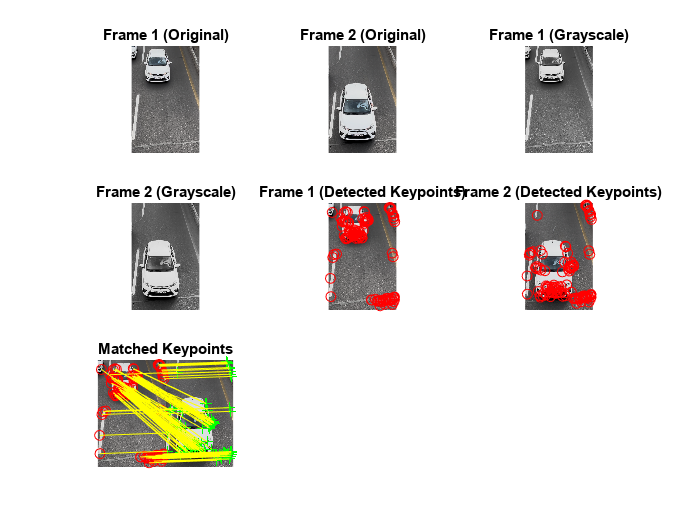

clc, clearvars, close all;
vidObj = VideoReader('video.mov');

timestamp = 0.25;
frame_number = round(vidObj.FrameRate * timestamp);
vidObj.CurrentTime = (frame_number - 1) / vidObj.FrameRate;
frame1 = readFrame(vidObj);

timestamp = 0.6;
frame_number = round(vidObj.FrameRate * timestamp);
vidObj.CurrentTime = (frame_number - 1) / vidObj.FrameRate;
frame2 = readFrame(vidObj);

figure;
subplot(3,3,1);
imshow(frame1);
title("Frame 1 (Original)");

subplot(3,3,2);
imshow(frame2);
title("Frame 2 (Original)");

gray1 = rgb2gray(frame1);
gray2 = rgb2gray(frame2);

subplot(3,3,3);
imshow(gray1);
title("Frame 1 (Grayscale)");

subplot(3,3,4);
imshow(gray2);
title("Frame 2 (Grayscale)");

points1 = detectSURFFeatures(gray1);
points2 = detectSURFFeatures(gray2);

[features1, validPoints1] = extractFeatures(gray1, points1);
[features2, validPoints2] = extractFeatures(gray2, points2);
indexPairs = matchFeatures(features1, features2);
matchedPoints1 = validPoints1(indexPairs(:, 1), :);
matchedPoints2 = validPoints2(indexPairs(:, 2), :);

subplot(3,3,5);
imshow(frame1);
hold on;
plot(matchedPoints1.Location(:,1), matchedPoints1.Location(:,2), 'ro');
title("Frame 1 (Detected Keypoints)");

subplot(3,3,6);
imshow(frame2);
hold on;
plot(matchedPoints2.Location(:,1), matchedPoints2.Location(:,2), 'ro');
title("Frame 2 (Detected Keypoints)");

displacements = matchedPoints2.Location - matchedPoints1.Location;
averageDisplacement = mean(sqrt(sum(displacements.^2, 2)));

subplot(3,3,7);
showMatchedFeatures(frame1, frame2, matchedPoints1, matchedPoints2, 'montage');
title("Matched Keypoints");


timeInterval = 0.5;
velocity = averageDisplacement / timeInterval;

fprintf('Velocity: %.2f pixels per second\n', velocity);

Velocity: 639.34 pixels per second


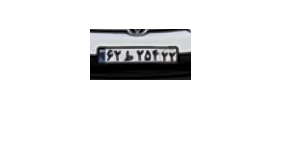

image = frame1;
template = imread('origin.jpg');
image = imcrop(image, [220, 300,100, 50]);
figure;
imshow(image);

image = imresize(image, [100, 150]);
template = imresize(template, [10, 20]); 
template = im2double(template);
image = im2double(image);    
correlationMapR = normxcorr2(template(:,:,1), image(:,:,1));
correlationMapG = normxcorr2(template(:,:,2), image(:,:,2));
    correlationMapB = normxcorr2(template(:,:,3), image(:,:,3));
    wR = 1;
    wG = 1;
    wB = 1;
    correlationMap = (wR * correlationMapR + wG * correlationMapG + wB * correlationMapB) / (wR + wG + wB);
    
    [maxCorrelationValue, maxIndex] = max(correlationMap(:));
    [maxRow, maxCol] = ind2sub(size(correlationMap), maxIndex);
    templateHeight = size(template, 1);
    templateWidth = size(template, 2);
    matchedRegionRow = maxRow - templateHeight + 1;
    matchedRegionCol = maxCol - templateWidth + 1;
    
   
    figure('Position',[0, 0, 800 400]);
    subplot(4,2,[1 3 5]);
    imshow(image)
    hold on;
    rectangle('Position', [matchedRegionCol, matchedRegionRow, templateWidth, templateHeight], 'EdgeColor', 'r', 'LineWidth', 2);
    rectangle('Position', [matchedRegionCol-10, matchedRegionRow-10, 7 * templateHeight, 2 * templateHeight], 'EdgeColor', 'g', 'LineWidth', 2);
    hold off;
    plate = imcrop(image, [matchedRegionCol-10, matchedRegionRow-10, 7 * templateHeight, 2 * templateHeight]);
    subplot(4,2,7);mybinaryfun(mygrayfun(imresize(plate, [100, 500])), 0.4);
    plate = mybinaryfun(mygrayfun(imresize(plate, [100, 500])), 0.4);
    imshow(plate);
    
    filtered = myremovecom(~plate, 170);
    background = myremovecom(~plate, 1200);
    characters = (filtered - background);
        
    subplot(4,2,2);
    imshow(~filtered);
    title('Removed noise');
    
    subplot(4,2,4);
    imshow(~background);
    title('Plate''s frame');
    
    subplot(4,2,6);
    imshow(~characters);
    title('Characters'); 
   
    detectedPlate = '';
    subplot(4,2,8)
    imshow(~characters);
    
    [labeled, n] = mysegmentation(characters);
    propied=regionprops(labeled,'BoundingBox');
    imshow(~characters);
    title('detected charachters')
    for m=1:size(propied,1)
        rectangle('Position',propied(m).BoundingBox,'EdgeColor','g','LineWidth',2)
    end
    for i = 1:n
        [row, col] = find(labeled == i);
        y = characters(min(row):max(row), min(col):max(col));
        corr_max = -2;
        i_max = 0;
        for j = 1:length(persianMapSet)
            character = persianMapSet{j, 2};
            y = imresize(y, size(persianMapSet{j,1}));
            corr_j = corr2(y, persianMapSet{j,1});
            if corr_j > corr_max
                corr_max = corr_j;
                i_max = j;
            end
        end
        if corr_max > 0.7
            detectedPlate = strcat(detectedPlate, persianMapSet{i_max,2});
        end
    end
    fprintf("Plate number : %s \n", detectedPlate);

function mapSet = getMapSet(Path)
    fileNames = dir(fullfile(Path, '*.bmp'));
    numOfFiles = length(fileNames);
    mapSet = cell(numOfFiles, 2);
    for i = 1:numOfFiles
        imagePath = fullfile(Path, fileNames(i).name);
        image = imread(imagePath);
        
        [~, fileName, ~] = fileparts(fileNames(i).name);
        mapSet{i, 1} = image;
        mapSet{i, 2} = fileName;
    end
end

function[grayscale_pic] = mygrayfun(pic)
    grayscale_pic = 0.299 .* pic(:,:,1) + 0.578 .* pic(:,:,2) + 0.114 .* pic(:,:,3);
end

function[binary_pic] = mybinaryfun(pic, threshold)
    binary_pic = pic > threshold;
end

function [labeledPic, n] = mysegmentation(pic)
    parts = detectParts(pic, 1);
    labeledPic = zeros(size(pic));
    n = numel(parts);    
    for i = 1:n
        part = parts{i};
        indices = sub2ind(size(labeledPic), part(:,1), part(:,2));
        labeledPic(indices) = i;
    end
end

function parts = detectParts(pic, threshold)
    [height, width] = size(pic);
    parts = {};
    toCheck = [];
    pairs = [];
    while true
        if isempty(toCheck)
            if size(pairs, 1) >= threshold
                parts{end + 1} = pairs;
            end
            pairs = [];
            [i, j] = findOne(pic);
            if i == -1
                break;
            end
            toCheck = [i, j];
            pic(i, j) = 0;
        else
            [row, col] = deal(toCheck(1, 1), toCheck(1, 2));
            pairs = [pairs; toCheck(1, :)];
            toCheck(1, :) = [];
            
            neighbors = [
                -1  0  
                 1  0  
                 0 -1
                 0  1 
                -1 -1
                -1  1
                 1 -1 
                 1  1
            ];
            
            for k = 1:size(neighbors, 1)
                r = row + neighbors(k, 1);
                c = col + neighbors(k, 2);
                if r >= 1 && r <= height && c >= 1 && c <= width && pic(r, c) == 1
                    pic(r, c) = 0;
                    toCheck = [toCheck; r, c];
                end
            end
        end
    end
    
    if size(pairs, 1) > threshold
        parts{end + 1} = pairs;
    end  
end

function [i, j] = findOne(matrice)
    [rows, cols] = find(matrice, 1);
    if isempty(rows)
        i = -1; j = -1;
    else
        i = rows; j = cols;
    end
end

function filteredPic = myremovecom(pic, threshold)
    parts = detectParts(pic, threshold);
    filteredPic = zeros(size(pic));
    
    for i = 1:numel(parts)
        part = parts{i};
        indices = sub2ind(size(filteredPic), part(:,1), part(:,2));
        filteredPic(indices) = 1;
    end
end
function parts = detectParts(pic, threshold)
    [height, width] = size(pic);
    parts = {};
    toCheck = [];
    pairs = [];
    while true
        if isempty(toCheck)
            if size(pairs, 1) >= threshold
                parts{end + 1} = pairs;
            end
            pairs = [];
            [i, j] = findOne(pic);
            if i == -1
                break;
            end
            toCheck = [i, j];
            pic(i, j) = 0;
        else
            [row, col] = deal(toCheck(1, 1), toCheck(1, 2));
            pairs = [pairs; toCheck(1, :)];
            toCheck(1, :) = [];
            
            neighbors = [
                -1  0  
                 1  0  
                 0 -1
                 0  1 
                -1 -1
                -1  1
                 1 -1 
                 1  1
            ];
            
            for k = 1:size(neighbors, 1)
                r = row + neighbors(k, 1);
                c = col + neighbors(k, 2);
                if r >= 1 && r <= height && c >= 1 && c <= width && pic(r, c) == 1
                    pic(r, c) = 0;
                    toCheck = [toCheck; r, c];
                end
            end
        end
    end
    
    if size(pairs, 1) > threshold
        parts{end + 1} = pairs;
    end  
end

function [i, j] = findOne(matrice)
    [rows, cols] = find(matrice, 1);
    if isempty(rows)
        i = -1; j = -1;
    else
        i = rows; j = cols;
    end
end